# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre:**

**Fecha:**

# Tema 4. Ejercicio 3. *Local Features*

El objetivo de esta práctica es mostrar el potencial de las demonimadas "*Local Features*". Para ello se va a buscar un objeto dentro de una escena utilizando los detectores y descriptores de caracteristicas locales.

clear all
close all

Step 1) Leer la imagen de referencia que contiene el objeto de interés.

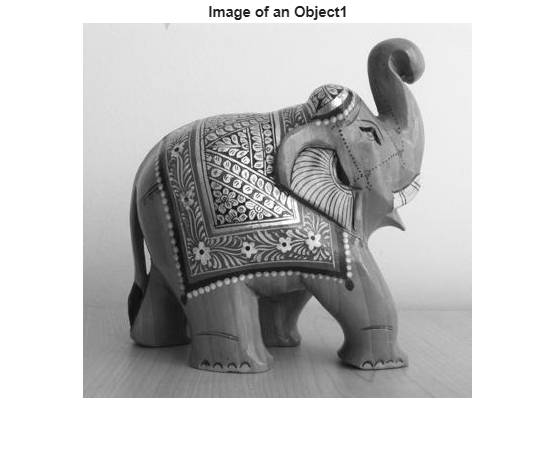

Object1Image = imread('elephant.jpg');
 
figure;
imshow(Object1Image);
title('Image of an Object1');

Se lee la escena que contiene al objeto de interés.

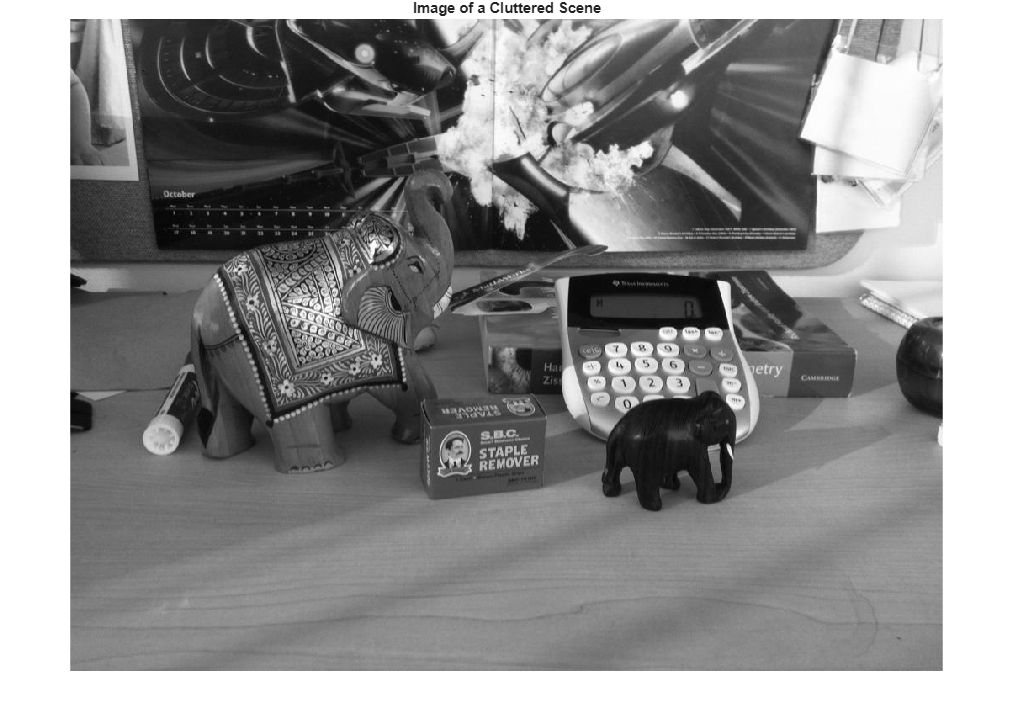

sceneImage = imread('clutteredDesk.jpg');
figure; 
imshow(sceneImage);
title('Image of a Cluttered Scene');

 Step 2) Se detectan las características locales del objeto y de la escena:

% Detect feature points in both images.
Object1Points = detectSURFFeatures(Object1Image);
scenePoints = detectSURFFeatures(sceneImage);

Se visualizan los puntos más fuertes que se encuentran en la imagen del objeto de referencia:

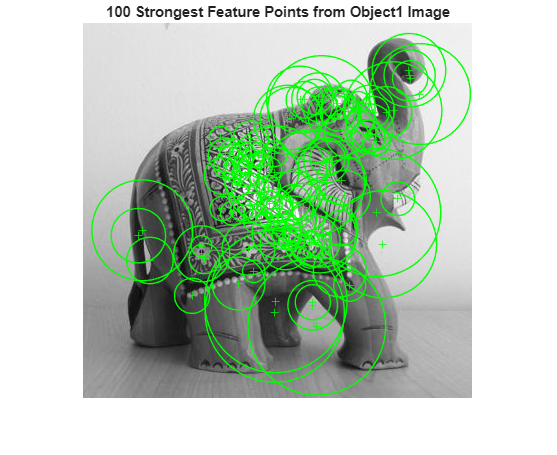

figure; 
imshow(Object1Image);
title('100 Strongest Feature Points from Object1 Image');
hold on;
plot(selectStrongest(Object1Points, 100));

se visualizan los puntos más fuertes que se encuentran en la imagen de la escena

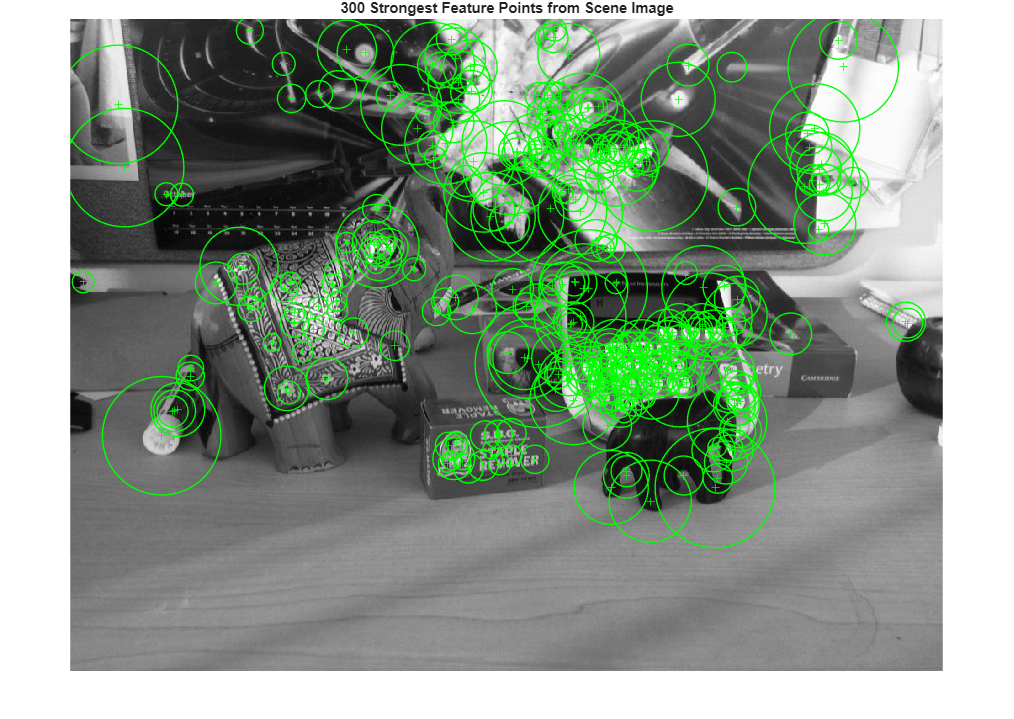

figure; 
imshow(sceneImage);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

Step 3) Se extraen los descriptores de caracterísitcas de ambas imágenes.

[Object1Features, Object1Points] = extractFeatures(Object1Image, Object1Points);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

Step 4) Se encuentran las coincidencias (*matches*) y se visualizan.

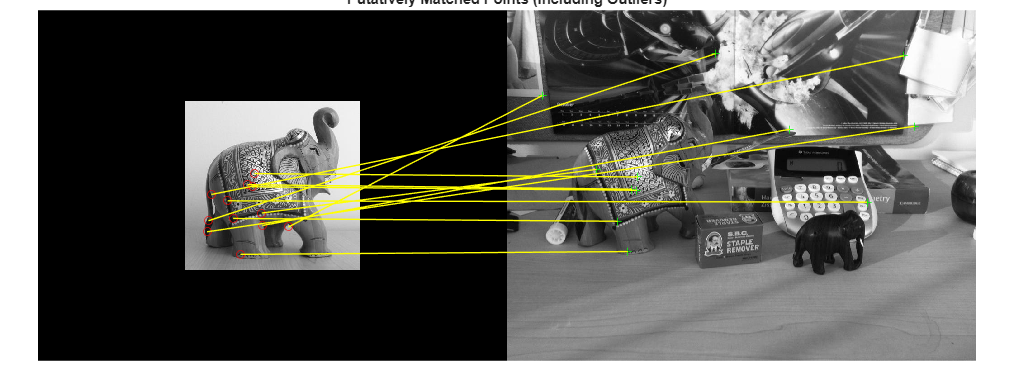

Object1Pairs = matchFeatures(Object1Features, sceneFeatures, 'MaxRatio', 0.9);

matchedObject1Points = Object1Points(Object1Pairs(:, 1), :);
matchedScenePoints = scenePoints(Object1Pairs(:, 2), :);
figure;
showMatchedFeatures(Object1Image, sceneImage, matchedObject1Points, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

Step 5) Se localiza el objeto en la escena usando las coincidencias. 

`estimateGeometricTransform` calcula la transformación relacionando los puntos coincidentes, a la vez que elimina los valores outliers. Esta transformación nos permite localizar el objeto en la escena.

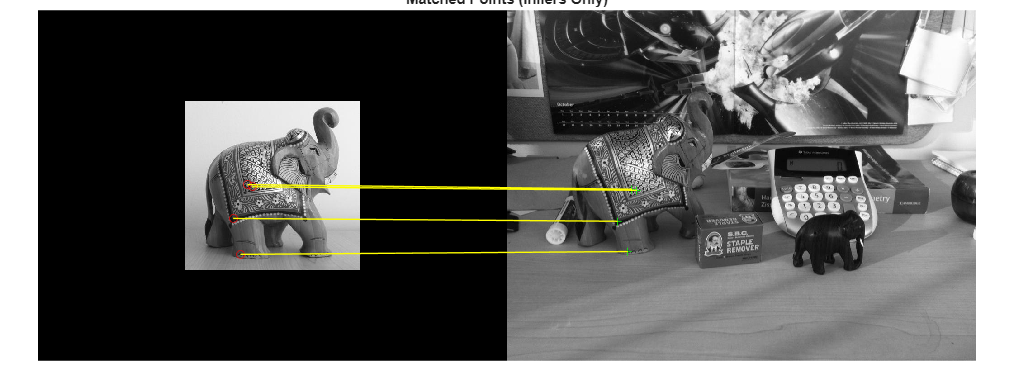

[tform, inlierObject1Points, inlierScenePoints] = estimateGeometricTransform(matchedObject1Points, matchedScenePoints, 'affine');

figure;
showMatchedFeatures(Object1Image, sceneImage, inlierObject1Points, inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

Se obtiene el polígono delimitador de la imagen de referencia.

Object1Polygon = [1, 1;...                           % top-left
        size(Object1Image, 2), 1;...                 % top-right
        size(Object1Image, 2), size(Object1Image, 1);... % bottom-right
        1, size(Object1Image, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon 

Se transforma el polígono en el sistema de coordenadas de la imagen de destino. El polígono transformado indica la ubicación del objeto1 en la escena.

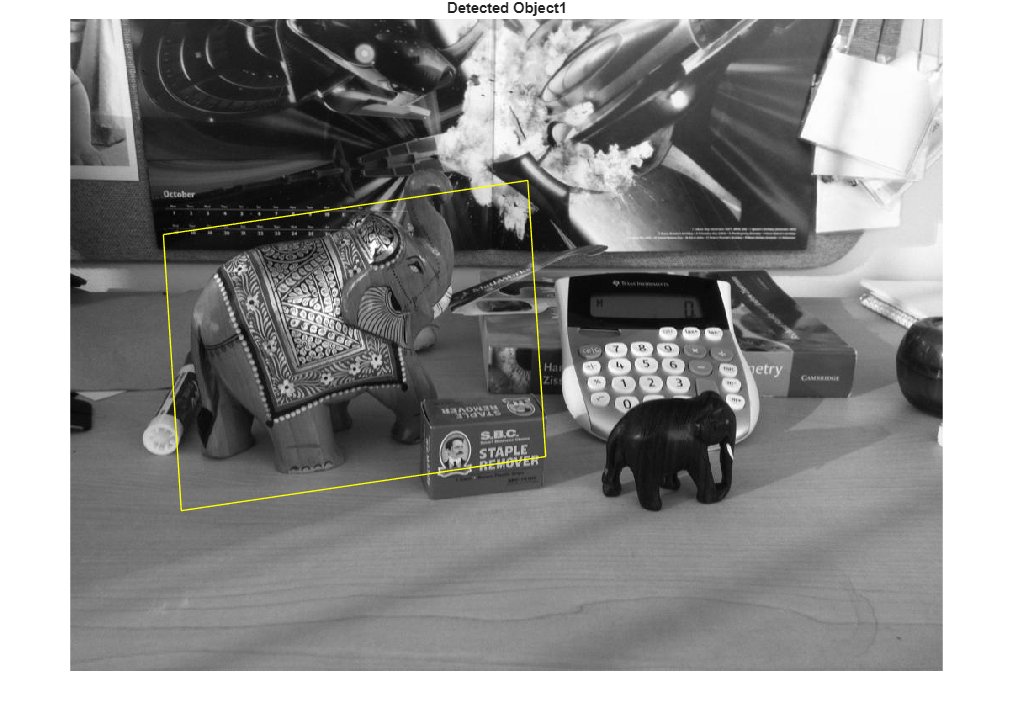

newObject1Polygon = transformPointsForward(tform, Object1Polygon);    

figure;
imshow(sceneImage);
hold on;
line(newObject1Polygon(:, 1), newObject1Polygon(:, 2), 'Color', 'y');
title('Detected Object1');

Se pide:

- Repita el proceso anterior pero buscando otro objeto de la escena, en este caso la caja de la grapadora, cuya imagen es `'stapleRemover.jpg'`. Además utilice el detector y descriptor BRISK ([`detectBRISKFeatures`](https://es.mathworks.com/help/vision/ref/detectbriskfeatures.html)). Compruebe cuantos pares de puntos empareja el algoritmo visualizando la salida de la función **matchFeatures**.

- Repita el punto 1, aplicando previamente un ruido gaussiano de varianza 0.001 a la imagen '**clutteredDesk.jpg**'. Compruebe cuantos pares de puntos empareja el algoritmo. ¿Es capaz de localizar el objeto? 

- Repita el punto 2, aplicando un ruido gaussiano de varianza 0.01. Compruebe cuantos pares de puntos empareja el algoritmo. ¿Esta vez es capaz de localizar el objeto? 

% === EJERCICIO 3.1: DETECTOR BRISK Y OBJETO GRAPADORA ===


% Paso 1) Leer imágenes
Object2Image = imread('stapleRemover.jpg'); % Nuevo objeto
sceneImage = imread('clutteredDesk.jpg');

% Paso 2) Detección de características BRISK
Object2Points = detectBRISKFeatures(Object2Image);
scenePoints = detectBRISKFeatures(sceneImage);

% Paso 3) Extracción de descriptores BRISK
[Object2Features, Object2Points] = extractFeatures(Object2Image, Object2Points);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

% Paso 4) Encontrar coincidencias (matches)
% BRISK es un descriptor binario, usa Hamming distance por defecto.
Object2Pairs = matchFeatures(Object2Features, sceneFeatures, 'MaxRatio', 0.9);

% *** COMPROBACIÓN REQUERIDA ***
numMatches = size(Object2Pairs, 1);
fprintf('Número de pares de puntos emparejados (BRISK/Grapadora): %d\n', numMatches);

Número de pares de puntos emparejados (BRISK/Grapadora): 11


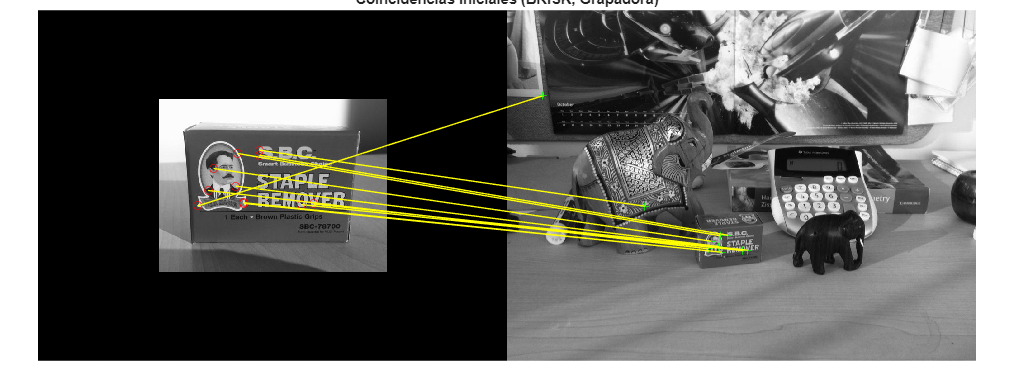


matchedObject2Points = Object2Points(Object2Pairs(:, 1), :);
matchedScenePoints = scenePoints(Object2Pairs(:, 2), :);

figure;
showMatchedFeatures(Object2Image, sceneImage, matchedObject2Points, ...
    matchedScenePoints, 'montage');
title('Coincidencias Iniciales (BRISK, Grapadora)');

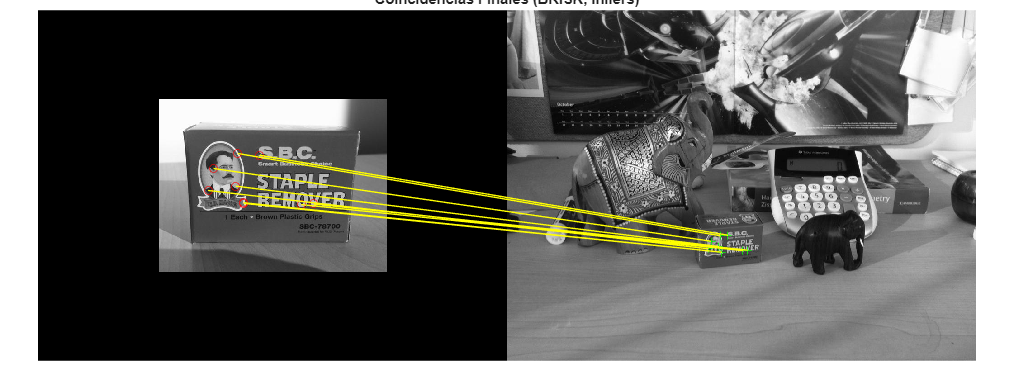


% Paso 5) Localización del objeto (Estimación de la Transformación)
[tform2, inlierObject2Points, inlierScenePoints] = ...
    estimateGeometricTransform(matchedObject2Points, matchedScenePoints, 'affine');

% Visualizar inliers
figure;
showMatchedFeatures(Object2Image, sceneImage, inlierObject2Points, inlierScenePoints, 'montage');
title('Coincidencias Finales (BRISK, Inliers)');

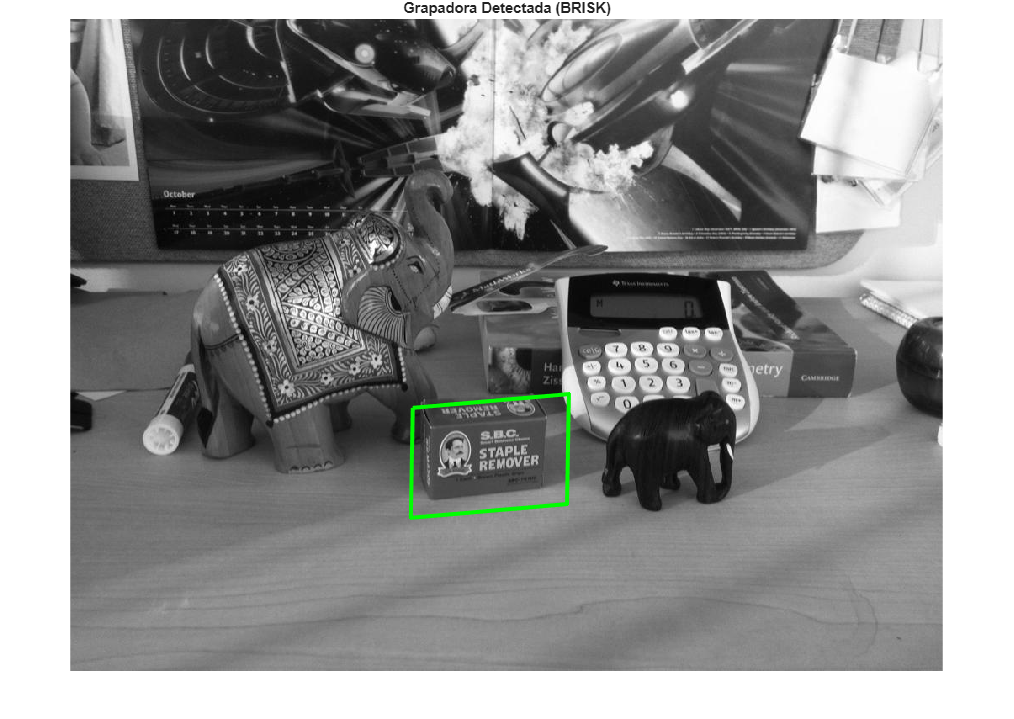


% Obtener y transformar el polígono delimitador
Object2Polygon = [1, 1; size(Object2Image, 2), 1; ...
    size(Object2Image, 2), size(Object2Image, 1); 1, size(Object2Image, 1); 1, 1];
newObject2Polygon = transformPointsForward(tform2, Object2Polygon);

% Visualizar el resultado
figure;
imshow(sceneImage);
hold on;
line(newObject2Polygon(:, 1), newObject2Polygon(:, 2), 'Color', 'g', 'LineWidth', 3);
title('Grapadora Detectada (BRISK)');
hold off;




% === EJERCICIO 3.2: RUÍDO GAUSSIANO (Varianza 0.001) y BRISK/Grapadora ===

Object2Image = imread('stapleRemover.jpg');
sceneImage = imread('clutteredDesk.jpg');

% 1. APLICAR RUIDO a la escena
sceneImageDouble = im2double(sceneImage);
noisySceneImage_001 = imnoise(sceneImageDouble, 'gaussian', 0, 0.001);
noisySceneImage_001_uint8 = im2uint8(noisySceneImage_001); % Convertir a uint8 para visualización

% 2. Detección de características BRISK
Object2Points = detectBRISKFeatures(Object2Image);
noisyScenePoints = detectBRISKFeatures(noisySceneImage_001_uint8); % Detección en la imagen con ruido

% 3. Extracción de descriptores
[Object2Features, Object2Points] = extractFeatures(Object2Image, Object2Points);
[noisySceneFeatures, noisyScenePoints] = extractFeatures(noisySceneImage_001_uint8, noisyScenePoints);

% 4. Encontrar coincidencias
Object2Pairs_001 = matchFeatures(Object2Features, noisySceneFeatures, 'MaxRatio', 0.9);

% *** COMPROBACIÓN REQUERIDA ***
numMatches_001 = size(Object2Pairs_001, 1);
fprintf('Número de pares de puntos emparejados (Ruido 0.001): %d\n', numMatches_001);

Número de pares de puntos emparejados (Ruido 0.001): 5


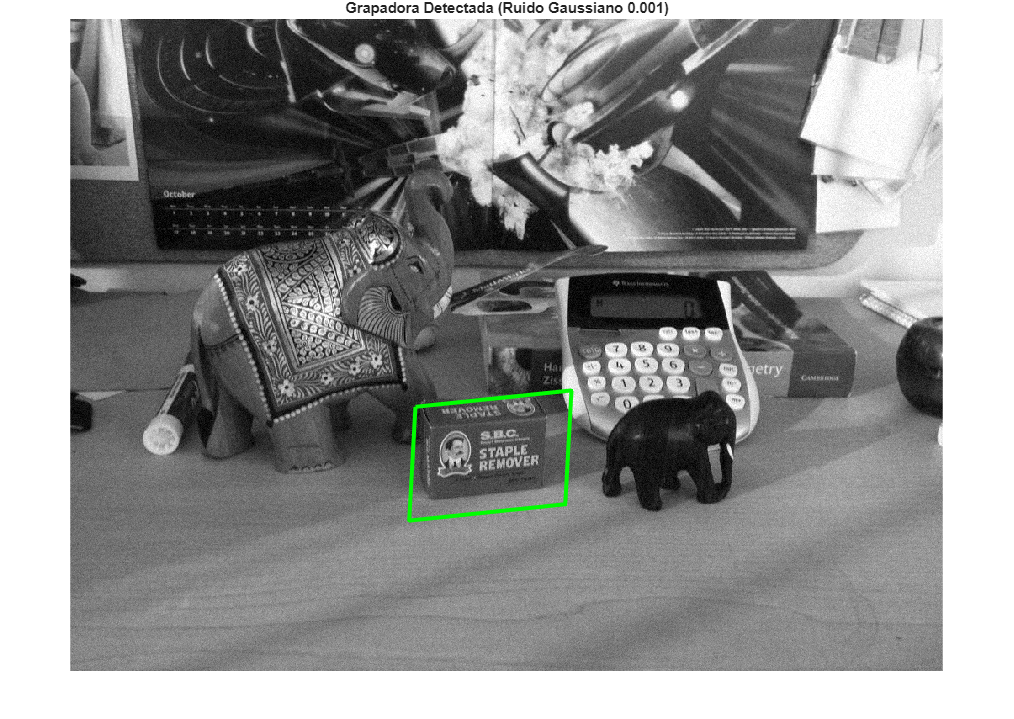


matchedObject2Points_001 = Object2Points(Object2Pairs_001(:, 1), :);
matchedScenePoints_001 = noisyScenePoints(Object2Pairs_001(:, 2), :);

% 5. Localización del objeto
[tform_001, inlierObject2Points_001, inlierScenePoints_001] = ...
    estimateGeometricTransform(matchedObject2Points_001, matchedScenePoints_001, 'affine');

% Obtener y transformar el polígono delimitador
Object2Polygon = [1, 1; size(Object2Image, 2), 1; ...
    size(Object2Image, 2), size(Object2Image, 1); 1, size(Object2Image, 1); 1, 1];
newObject2Polygon_001 = transformPointsForward(tform_001, Object2Polygon);

% Visualizar el resultado
figure;
imshow(noisySceneImage_001); % Mostrar la imagen con ruido
hold on;
line(newObject2Polygon_001(:, 1), newObject2Polygon_001(:, 2), 'Color', 'g', 'LineWidth', 3);
title('Grapadora Detectada (Ruido Gaussiano 0.001)');
hold off;


% === Respuesta a la pregunta ===
% ¿Es capaz de localizar el objeto?
% R: Sí, con una varianza de 0.001, la cantidad de ruido es relativamente baja. Los descriptores BRISK (que son menos sensibles a la iluminación/ruido que otros) deberían ser capaces de encontrar suficientes **inliers** para calcular la matriz de transformación y localizar el objeto con precisión.





% === EJERCICIO 3.3: RUÍDO GAUSSIANO (Varianza 0.01) y BRISK/Grapadora ===


Object2Image = imread('stapleRemover.jpg');
sceneImage = imread('clutteredDesk.jpg');

% 1. APLICAR RUIDO (más alto)
sceneImageDouble = im2double(sceneImage);
noisySceneImage_01 = imnoise(sceneImageDouble, 'gaussian', 0, 0.01);
noisySceneImage_01_uint8 = im2uint8(noisySceneImage_01);

% 2. Detección de características BRISK
Object2Points = detectBRISKFeatures(Object2Image);
noisyScenePoints = detectBRISKFeatures(noisySceneImage_01_uint8); % Detección en la imagen con ruido

% 3. Extracción de descriptores
[Object2Features, Object2Points] = extractFeatures(Object2Image, Object2Points);
[noisySceneFeatures, noisyScenePoints] = extractFeatures(noisySceneImage_01_uint8, noisyScenePoints);

% 4. Encontrar coincidencias
Object2Pairs_01 = matchFeatures(Object2Features, noisySceneFeatures, 'MaxRatio', 0.9);

% *** COMPROBACIÓN REQUERIDA ***
numMatches_01 = size(Object2Pairs_01, 1);
fprintf('Número de pares de puntos emparejados (Ruido 0.01): %d\n', numMatches_01);

Número de pares de puntos emparejados (Ruido 0.01): 2


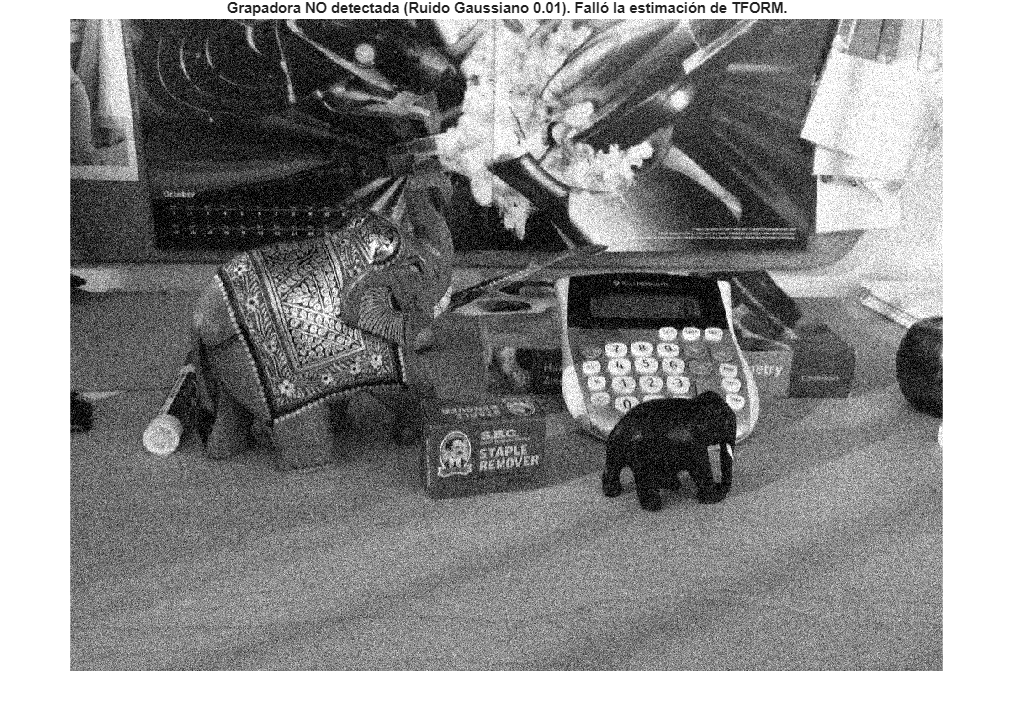


matchedObject2Points_01 = Object2Points(Object2Pairs_01(:, 1), :);
matchedScenePoints_01 = noisyScenePoints(Object2Pairs_01(:, 2), :);

% 5. Localización del objeto
% (El estimateGeometricTransform puede fallar si no hay suficientes inliers)
try
    [tform_01, inlierObject2Points_01, inlierScenePoints_01] = ...
        estimateGeometricTransform(matchedObject2Points_01, matchedScenePoints_01, 'affine');

    % Obtener y transformar el polígono delimitador
    Object2Polygon = [1, 1; size(Object2Image, 2), 1; ...
        size(Object2Image, 2), size(Object2Image, 1); 1, size(Object2Image, 1); 1, 1];
    newObject2Polygon_01 = transformPointsForward(tform_01, Object2Polygon);

    % Visualizar el resultado
    figure;
    imshow(noisySceneImage_01);
    hold on;
    line(newObject2Polygon_01(:, 1), newObject2Polygon_01(:, 2), 'Color', 'r', 'LineWidth', 3);
    title('Grapadora Detectada (Ruido Gaussiano 0.01)');
    hold off;

    localizationSuccess = true;
catch
    localizationSuccess = false;
    figure;
    imshow(noisySceneImage_01);
    title('Grapadora NO detectada (Ruido Gaussiano 0.01). Falló la estimación de TFORM.');
end


% === Respuesta a la pregunta ===
% ¿Esta vez es capaz de localizar el objeto?
% R: La detección será **mucho más difícil** y la localización es **probable que falle** (o sea inexacta).
% El ruido alto (varianza 0.01) distorsiona significativamente los patrones de intensidad local utilizados por el detector BRISK para establecer la orientación y la estructura del descriptor. Esto lleva a:
% 1. **Menor número de matches** (Object2Pairs_01).
% 2. **Menor calidad de los matches**, lo que resulta en pocos **inliers** después del algoritmo RANSAC dentro de `estimateGeometricTransform`.
% Si el número de inliers es insuficiente (generalmente menos de 3 para una transformación afín), la función `estimateGeometricTransform` fallará, indicando que el objeto no puede ser localizado de manera confiable.



